# Homework 2

ME599 Data Analysis

Aaron Cornelius

2020-9-17

Throughout this document, Matlab code is placed next to the figures or calculations that are being performed for convenience.

## Problem 1

Analytically determine the Fourier transform $X\left(\omega \right)$ of the boxcar window function, and solve for both magnitude and phase:


$$x\left(t\right)=\left\lbrace \begin{array}{ll}
A & 0\le t\le T\\
0 & t<0,t>T
\end{array}\right.$$


Plot $X\left(\omega \right)$ in the complex plane, and produce graphs of the magnitude $\left|X\left(\textrm{fT}\right)\right|$ and phase $\angle X\left(\textrm{fT}\right)$ as a function of $\textrm{ft}$ with $A=1,T=1$ for $0\le \textrm{fT}\le 10$.

What happens if you change $T$ and/or $A$, but keep $A\cdot T$ constant?

The Fourier transform is defined as:


$$X\left(\omega \right)=\int_{-\infty }^{\infty } x\left(t\right)\cdot e^{-j\omega \;t} \;\mathrm{dt}$$


For this problem, it can be written as:


$$X\left(\omega \right)=A\int_0^T e^{-j\omega \;t} \;\mathrm{dt}$$


From an integral table, $\int e^{\textrm{ax}} \;\textrm{dx}=\frac{1}{a}e^{\textrm{ax}}$. Therefore:


$$X\left(\omega \right)=\frac{-A}{j\;\omega }\left(e^{-j\;\omega \;T} -e^{-j\;\omega \cdot 0} \right)$$


By multiplying by $\frac{j}{j}$ and applying $e^0 =1$, this can be simplified to:


$$X\left(\omega \right)=\frac{j\;A}{\omega }\left(e^{-j\;\omega \;T} -1\right)$$


Applying Euler's identity $e^{i\;x} =\mathrm{cos}\;x+i\;\mathrm{sin}\;x$, this can be rewritten:


$$X\left(\omega \right)=\frac{j\;A}{\omega }\left(\mathrm{cos}\left(-\omega T\right)+j\;\mathrm{sin}\left(-\omega T\right)-1\right)$$


Since $\mathrm{cos}\left(-x\right)=\mathrm{cos}\left(x\right)$ and $\mathrm{sin}\left(-x\right)=-\mathrm{sin}\left(x\right)$, this simplifies to:


$$X\left(\omega \right)=\frac{j\;A}{\omega }\left(\mathrm{cos}\left(\omega T\right)-j\;\mathrm{sin}\left(\omega T\right)-1\right)$$



$$X\left(\omega \right)=\frac{A}{\omega }\left(\mathrm{sin}\left(\omega T\right)+j\left(\mathrm{cos}\left(\omega T\right)-1\right)\right)$$


This can be seperated into real and imaginary components:


$${X\left(\omega \right)}_{\mathrm{real}} =\frac{A}{\omega }\left(\mathrm{sin}\left(\omega T\right)\right),{X\left(\omega \right)}_{\mathrm{imag}} =\frac{A}{\omega }\left(\mathrm{cos}\left(\omega T\right)-1\right)$$


The magnitude $\left|X\left(\omega \right)\right|$ is defined as $\left|X\left(\omega \right)\right|=\sqrt{{X\left(\omega \right)}_{\mathrm{real}}^2 +{X\left(\omega \right)}_{\mathrm{imag}}^2 }$:


$$\left|X\left(\omega \right)\right|=\frac{A}{\omega }\left(\sqrt{{\left(\mathrm{sin}\left(\omega T\right)\right)}^2 +{\left(\mathrm{cos}\left(\omega T\right)-1\right)}^2 }\right)$$


The phase angle $\angle X\left(\omega \right)$ is defined as $\angle X\left(\omega \right)=\mathrm{atan2}\left({X\left(\omega \right)}_{\mathrm{imag}} ,{X\left(\omega \right)}_{\mathrm{real}} \right)$. The use of $\mathrm{atan2}$ is necessary since it can return phase angles from $0:2\pi$, while $\mathrm{atan}$ would only return phase angles from $-\frac{\pi }{2}:\frac{\pi }{2}$. Since the ratio between the real and imaginary values is what's important, the $\frac{A}{\omega }$ can be factored out:


$$\angle X\left(\omega \right)=\mathrm{atan2}\left(\mathrm{cos}\left(\omega T\right)-1,\mathrm{sin}\left(\omega T\right)\right)$$


$X\left(\omega \right)$ can be plotted in the complex plane. For $A=T=1$, it starts with a magnitude of 1 in the real axis and 0 in the imaginary axis, then spirals in towards 0,0.

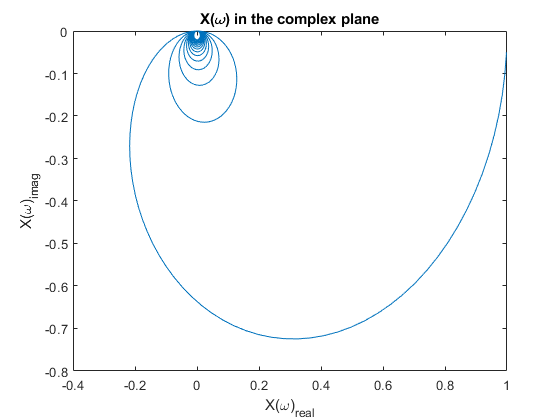

figure
omega = 0.1:0.1:10000;
X_omega = 1./omega .* (sin(omega) + 1j * cos(omega) - 1j);
plot(X_omega(1:1000))
xlabel('X(\omega)_{real}')
ylabel('X(\omega)_{imag}')
title('X(\omega) in the complex plane')

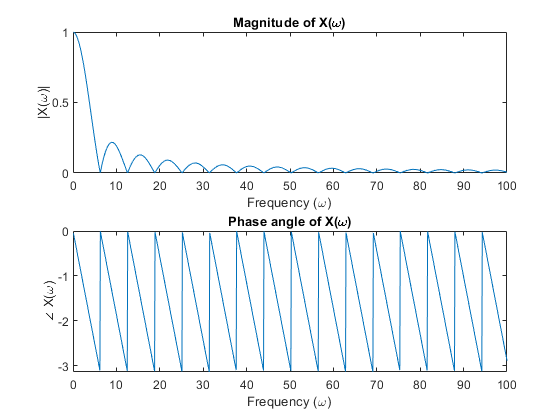

figure
subplot(2,1,1)
plot(omega, abs(1./omega .* ((sin(omega).^2) + (cos(omega) -1).^2 ).^0.5));
xlim([0 100])
title('Magnitude of X(\omega)')
xlabel('Frequency (\omega)')
ylabel('|X(\omega)|')
subplot(2,1,2)
plot(omega, atan2(cos(omega)-1, sin(omega)))
xlabel('Frequency (\omega)')
ylabel('\angle X(\omega)')
title('Phase angle of X(\omega)')
xlim([0 100])

Changing the values A and T such that $A\cdot T$ is constant essentially acts as a horizontal scaling factor for the Fourier transform. The magnitude of each of the oscillations in the FFT is identical, but the period is either increased or decreased inversely proportional to the change in $T$. When graphed in the complex plane, the functions would appear identical since the frequency is not visualized. However, when graphing the magnitude and phase angle versus frequency the horizontal scaling can be easily seen:

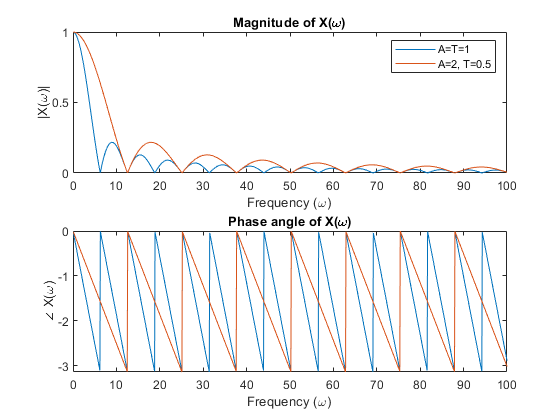

figure
subplot(2,1,1)
plot(omega, abs(1./omega .* ((sin(omega).^2) + (cos(omega) -1).^2 ).^0.5));
hold on
plot(omega, abs(2./omega .* ((sin(0.5*omega).^2) + (cos(0.5*omega) -1).^2 ).^0.5));
xlim([0 100])
title('Magnitude of X(\omega)')
xlabel('Frequency (\omega)')
ylabel('|X(\omega)|')
legend(["A=T=1" "A=2, T=0.5"]);
subplot(2,1,2)
plot(omega, atan2(cos(omega)-1, sin(omega)))
hold on
plot(omega, atan2(cos(0.5*omega)-1, sin(0.5*omega)))
xlabel('Frequency (\omega)')
ylabel('\angle X(\omega)')
title('Phase angle of X(\omega)')
xlim([0 100])

## Problem 2

B&P 1.3: If a stationary random process $\left\lbrace x\left(t\right)\right\rbrace$ has a mean value $\mu_x$, what is the limiting value of the autocorrelation function $R_{\textrm{xx}} \left(\tau \right)$ as the time delay $\tau$ becomes long? Explain your conclusions.

The auto-correlation function is defined as $R_{\mathrm{xx}} \left(\tau \right)=E\left\lbrack x\left(t\right)\;x\left(t+\tau \right)\right\rbrack$. As the time-delay $\tau$ increases, the correlation between $x\left(t\right)$ and $x\left(t+\tau \right)$ approaches 0. In other words, for a large enough delay $\tau$, the samples can be treated as independent. The expectation of the product of two independant random variables is equal to the product of the expectations of each variable. Therefore, $E\left\lbrack x\left(t\right)\;x\left(t+\tau \right)\right\rbrack =E\left\lbrack x\left(t\right)\right\rbrack \;E\left\lbrack x\left(t+\tau \right)\right\rbrack$. Since the process is stationary and the mean is known to be $\mu_x$, the expectations for the samples are $E\left\lbrack x\left(t\right)\right\rbrack =E\left\lbrack x\left(t+\tau \right)\right\rbrack =\mu_x$. Therefore:


$$\lim_{\tau \to \infty } {\;R}_{\mathrm{xx}} \left(\tau \right)=\mu_x^2$$


## Problem 3

B&P 1.4: An estimate is known to have a mean square error 0.25 and a bias error of 0.40. Determine the variance of the estimate.

From equation 1.17, it is known that $E\left\lbrack {\left(\phi^ˆ +\phi \right)}^2 \right\rbrack =\mathrm{Var}\left\lbrack \phi^ˆ \right\rbrack +{\left(b\left\lbrack \phi^ˆ \right\rbrack \right)}^2$. Therefore:


$$0\ldotp 4=\mathrm{Var}\left\lbrack \phi^ˆ \right\rbrack +0\ldotp {25}^2$$



$$\Rightarrow \mathrm{Var}\left\lbrack \phi^ˆ \right\rbrack =0\ldotp 4-0\ldotp {25}^2 =0\ldotp 3375$$


## Problem 4

B&P 1.5: In problem 1.4, if the quantity being estimated has a true value of $\phi =5$, what is the normalized rms error of the estimate?

From equation 1.18, the normalized root-mean-square (or rms) error is defined as: $\epsilon \left\lbrack \phi^ˆ \right\rbrack =\frac{\sqrt{E\left\lbrack {\left(\phi^ˆ -\phi \right)}^2 \right\rbrack }}{\phi }$

Since $\phi =5$ and $E\left\lbrack {\left(\phi^ˆ -\phi \right)}^2 \right\rbrack =0\ldotp 25$:


$$\epsilon \left\lbrack \phi^ˆ \right\rbrack =\frac{\sqrt{0\ldotp {25}^2 }}{5}=\frac{0\ldotp 25}{5}=0\ldotp 05$$


## Problem 5

B&P 2.1: If an input $x\left(t\right)$ produces an output $y\left(t\right)=x\left(t\right)\left|x\left(t\right)\right|$, prove that the input/output relationship is nonlinear.

For this relationship to be linear, it would have to meet two requirements. First, it would have to be additive such that $y\left(t_1 +t_2 \right)=y\left(t_1 \right)+y\left(t_2 \right)$. Second, it would have to be homogenous such that $y\left(a\cdot t\right)=a\cdot y\left(t\right)$ for any constant value $a$.

Neither of these are true for this equation. The additive property requires that $y\left(t_1 +t_2 \right)=x\left(t_1 \right)|x\left(t_1 \right)|+x\left(t_2 \right)|x\left(t_2 \right)|$. Depending on the signs of $x\left(t_1 \right),x\left(t_2 \right)$, this will take the form of $y\left(t_1 +t_2 \right)=\pm {x\left(t_1 \right)}^2 \pm {x\left(t_2 \right)}^2$. For positive values of $x\left(t\right)$, the term will be positive, while negative values of $x\left(t\right)$ will have the term be negative due to the absolute value.

However, the actual form does not match this. The actual form of $y\left(t_1 +t_2 \right)$ is $y\left(t_1 +t_2 \right)=x\left(t_1 +t_2 \right)\cdot \left|x\left(t_1 +t_2 \right)\right|$. This can be simplified into a piecewise equation:


$$y\left(t_1 +t_2 \right)=\left\lbrace \begin{array}{ll}
{x\left(t_1 +t_2 \right)}^2  & x\left(t_1 +t_2 \right)\ge 0\\
{-x\left(t_1 +t_2 \right)}^2  & x\left(t_1 +t_2 \right)<0
\end{array}\right.$$


This does not match the required form to be additive. Therefore, the function is not additive, and thus also nonlinear.

## Problem 6

In a calibration test, 10 measurements using a digital voltmeter have been made of the voltage on a battery that is known to have a true voltage of 6.11 V. The readings are: 5.98, 6.05, 6.10, 6.06, 5.99, 5.96, 6.02, 6.03, 5.99. What is the bias error caused by the voltmeter? In this sample set, what was the largest *random* error?

The bias error is found by taking the difference between the mean reading and the true value $b\left\lbrack \phi^ˆ \right\rbrack =E\left\lbrack \phi^ˆ \right\rbrack -\phi =0\ldotp 4$:

measurements = [5.98 6.05 6.10 6.06 5.99 5.96 6.02 6.03 5.99];
biasError = mean(measurements) - 6.11;

The mean of the measurements is 6.02 volts, so the bias error is equal to -0.09 volts.

The random error is evaluated by comparing the difference between the mean measurement and each individual measurement. The largest magnitude random error is 0.08, found on the third measurement of 6.10 volts.

randomErrors = measurements - 6.11 - biasError

randomErrors =    -0.0400    0.0300    0.0800    0.0400   -0.0300   -0.0600         0    0.0100   -0.0300


maxBiasError = max(randomErrors)

maxBiasError = 0.0800

## Problem 7

Write a function to perfom the reverse arrangement test. The function should recieve a random variable as an input and split it into a user-defined number of sample records of equal length and return the total number of reversals of the mean-square value of each record. Validate your code using the data in Ex. 4.4.

Then use real data (if available) and matlab-generated data to test your code. First, use stationary random data, then use nonstationary data. Include code, plots of the data used (record snippets, histograms), and explain your observations and results.

This function is defined at the end of the document. The code will first be tested using the data from example 4.4. This function should return 86 reverse arrangements and a logical true (or 1) value for accepting the hypothesis that the data are stationary at 95% confidence.

% Example 4.4 data
example44Data = [...
    5.2 6.2 3.7 6.4 3.9 ...
    4.0 3.9 5.3 4.0 4.6 ...
    5.9 6.5 4.3 5.7 3.1 ...
    5.6 5.2 3.9 6.2 5.0];

The data are visualized:

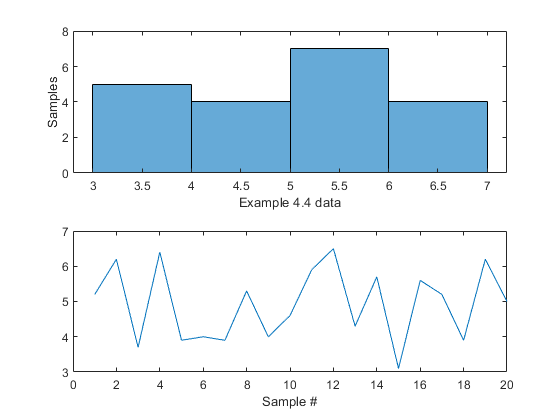

% Visualize data using a histogram and plot
figure
subplot(2,1,1)
histogram(example44Data)
xlabel('Example 4.4 data')
ylabel('Samples')
subplot(2,1,2)
plot(example44Data)
xlabel('Sample #')

There are only a small number of data points, so it is difficult to determine whether they are stationary visually, but the overall range does appear to be constant across the entire sample set, and there are no oddities in the histogram that immediately stand out. Therefore, stationarity will be checked using the reverse arrangement test.

[reversalCount, reversalList, accept] = reverseArrangementTest(example44Data, 20, 0.05);
assert(reversalCount == 86);
assert(all(reversalList == [10 15 1 15 1 3 1 7 2 3 7 8 2 5 0 3 2 0 1]'));
assert(accept)
reversalCount

reversalCount = 86

accept

accept = logical
   1


Since it returns 86 values and accepts the hypothesis of stationarity, this check passes.

Next, the algorithm will be confirmed on a larger data set of one million samples drawn from a simple Gaussian distribution with $\sigma =1,\mu =0$. Since all these samples are drawn independently, the distribution should be stationary. This will be checked with a 10% significance level. Since the data set is large, it will be divided into 100 records.

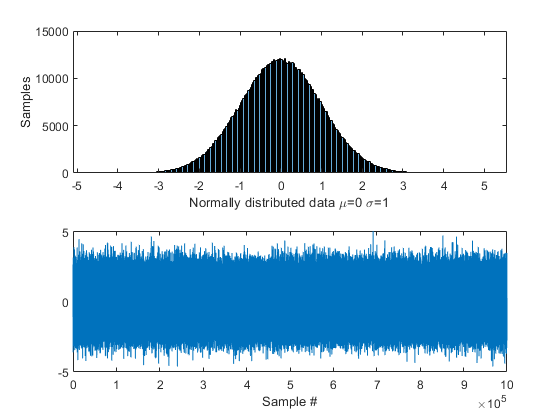

% Sample data from a normal distribution
normalSamples = randn(1000000,1);

% Visualize data
figure
subplot(2,1,1)
histogram(normalSamples)
xlabel('Normally distributed data \mu=0 \sigma=1')
ylabel('Samples')
subplot(2,1,2)
plot(normalSamples)
xlabel('Sample #')


% Perform reverse arrangement test
[reversalCount, ~, accept] = reverseArrangementTest(normalSamples,100,0.02);
reversalCount

reversalCount = 2663

accept

accept = logical
   1


There were approximately 2530 reversals in this data set. For a 100 record set and a 10% significance limit, the lower and upper limits for the reversal count are 2198 and 2751 respectively. Since 2530 is between those two values, the hypothesis of stationarity is accepted.

Now the the data will be transformed by applying a small slope to them. Over the course of the one million samples, the mean will increase from 0 to 1.

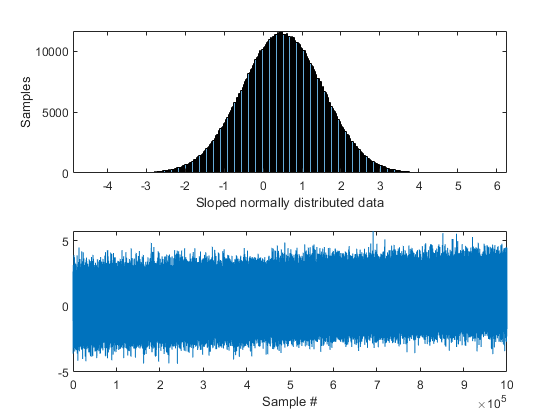

slopedNormalSamples = normalSamples + [linspace(0, 1, length(normalSamples))]';
% Visualize data
figure
subplot(2,1,1)
histogram(slopedNormalSamples)
xlabel('Sloped normally distributed data')
ylabel('Samples')
subplot(2,1,2)
plot(slopedNormalSamples)
xlabel('Sample #')

While the slope is small, it can clearly be seen over the course of the entire ensemble. The shift can also be seen in the histogram: the mean has moved up to 0.5, which is the average mean over the whole sample length.

[reversalCount, ~, accept] = reverseArrangementTest(slopedNormalSamples, 100, 0.10);
reversalCount

reversalCount = 137

accept

accept = logical
   0


As before, the reversal count must be between 2198 and 2751 to accept the hypothesis of stationarity. However, the actual number of reversals is around 110, well outside the limits. Thus, it is concluded that the data are not stationary.

Lastly, two experimental data sets will be analyzed. These data sets are deflection data taken during milling stability tests. A workpiece is mounted on a flexure and a milling cut is taken on the workpiece (the flexure is shown in the below image. The workpiece is the block on top of the flexure: the cut along one side is the material removed during the milling pass.) The deflection of the flexure during the cut is recorded using a capacitance probe. The specific probe chosen for this project has a range of 1.6mm and noise on the order of 5$\mu$m. Both data sets are 1 second long, and were sampled at a rate of 20 kHzs.

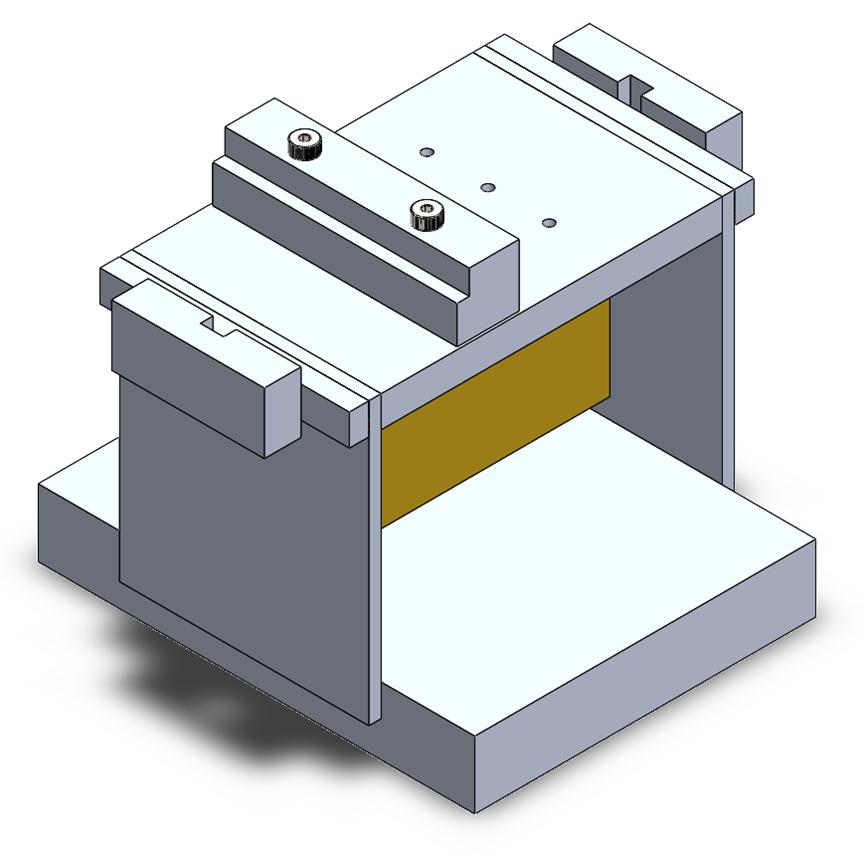

The first data set that will be analyzed is of a successful machining pass. A subset of the data is shown below so the form can be visualized: the vibration of the flexure is a repeating periodic sine wave. This same periodic pattern repeats over the whole data set with very low noise. The histogram also agrees with this: it matches the general form that would be expected of the histogram of a sine wave.

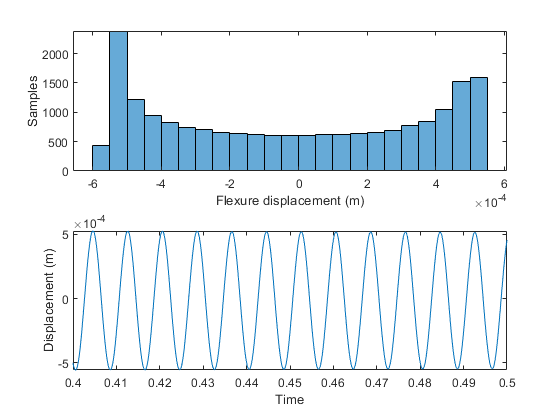

load StableDisplacementData.mat
% Visualize data
figure
subplot(2,1,1)
histogram(displacement)
xlabel('Flexure displacement (m)')
ylabel('Samples')
subplot(2,1,2)
plot(0:0.00005:1, displacement)
xlim([0.4 0.5])
xlabel('Time')
ylabel('Displacement (m)')

Since the data are very close to periodic, it is expected that they are stationary. This is checked using the reverse arrangement test with 100 records and a 10% significance limit.

[reversalCount, ~, accept] = reverseArrangementTest(displacement, 100, 0.10);
reversalCount

reversalCount = 2712

accept

accept = logical
   1


The hypothesis was accepted, indicating that the displacement results stationary.

Next, a different measurement will be analyzed. This measurement was collected under similar circumstances. However, partway through the cut the flutes of the milling tool became jammed with chips. Once this happened, the tool was no longer able to cleanly shear the aluminum. As a result, the signal is not constant through the cut. While it initially looks like a normal milling cut (up through ~0.3 seconds in the chart below), after that it changes dramatically and becomes much choppier.

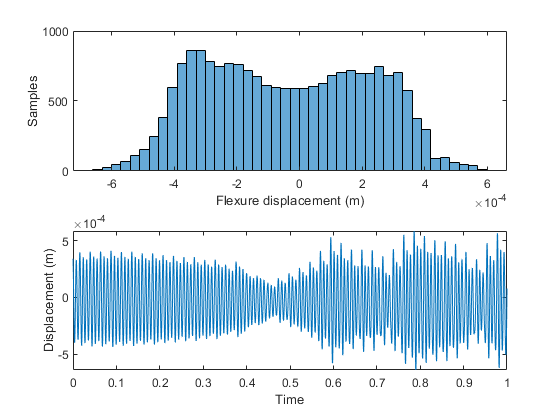

load CloggedFluteDisplacementData.mat
% Visualize data
figure
subplot(2,1,1)
histogram(displacement)
xlabel('Flexure displacement (m)')
ylabel('Samples')
subplot(2,1,2)
plot(0:0.00005:1, displacement)
xlabel('Time')
ylabel('Displacement (m)')

From a visual inspection, this should not be stationary. The dynamics change dramatically partway through the cut. This is checked using the reverse arrangement test with 100 records and a 10% significance limit.

[reversalCount, ~, accept] = reverseArrangementTest(displacement, 100, 0.10);
reversalCount

reversalCount = 2162

accept

accept = logical
   0


As seen, the stationarity hypothesis was rejected. The reversal count is not dramatically lower than the cutoff, but it is enough to demonstrate that there was some change partway through the data.

Reverse arrangement function:

function [reversals, reversalList, accept] = ...
    reverseArrangementTest(data, recordCount, significance)
    
    % Determine the indices to split at
    splitIndices = round(linspace(1, length(data)+1, recordCount+1));
    
    % Get the mean-square values for each record
    meanSquareValues = zeros(recordCount,1);
    for i = 1:length(splitIndices)-1
        record = data(splitIndices(i):splitIndices(i+1)-1);
        meanSquareValues(i) = (mean(record.^2));
    end
    
    % Get the list of reversals
    reversals = 0;
    reversalList = zeros(recordCount-1,1);
    for i = 1:length(meanSquareValues)-1
        diffs = meanSquareValues(i)-meanSquareValues(i+1:end);
        reversalList(i) = sum(diffs>0);
        reversals = reversals + sum(diffs>0);
    end
    
    % Table A.6
    percentageRecordCounts = [10 12 14 16 18 20 30 40 50 60 70 80 90 100];
    percentageBounds = [...
        9 16 24 34 45 59 152 290 473 702 977 1299 1668 2083; % 99%
        11 18 27 38 50 64 162 305 495 731 1014 1344 1721 2145; % 97.5%
        13 21 30 41 54 69 171 319 514 756 1045 1382 1766 2198; % 95%
        31 44 60 78 98 120 263 460 710 1013 1369 1777 2238 2751; % 5%
        33 47 63 81 102 125 272 474 729 1038 1400 1815 2283 2803; % 2.5%
        35 49 66 85 17 130 282 489 751 1067 1437 1860 2336 2866; % 1%
    ];

    % Find the closest record count to one of the values from A.6
    [~, recordCountIndex] = min(abs(percentageRecordCounts - recordCount));

    % Check the reversal count versus table A.6
    if significance == 0.02
        accept = reversals >= percentageBounds(1, recordCountIndex) ...
            && reversals <= percentageBounds(6, recordCountIndex);
    elseif significance == 0.05
        accept = reversals >= percentageBounds(2, recordCountIndex) ...
            && reversals <= percentageBounds(5, recordCountIndex);
    elseif significance == 0.10
        accept = reversals >= percentageBounds(3, recordCountIndex) ...
            && reversals <= percentageBounds(4, recordCountIndex);
    else
        error('Invalid significance value. Confidence must be 0.02, 0.05, or 0.1')
    end

end